# System identification of mars rover drive chain

## Generate input data


h = 0.01; % Sampling period
uu = idinput(6000, 'rbs', [0, 0.8]);
currentMagnitude = 1e-2;
u1 = currentMagnitude*uu(1:3000);
u1v = currentMagnitude*uu(3001:6000);
t = (0:2999)'*h;
input1 = cat(2, t, u1);
input1v = cat(2, t, u1v);


## Load simulation results

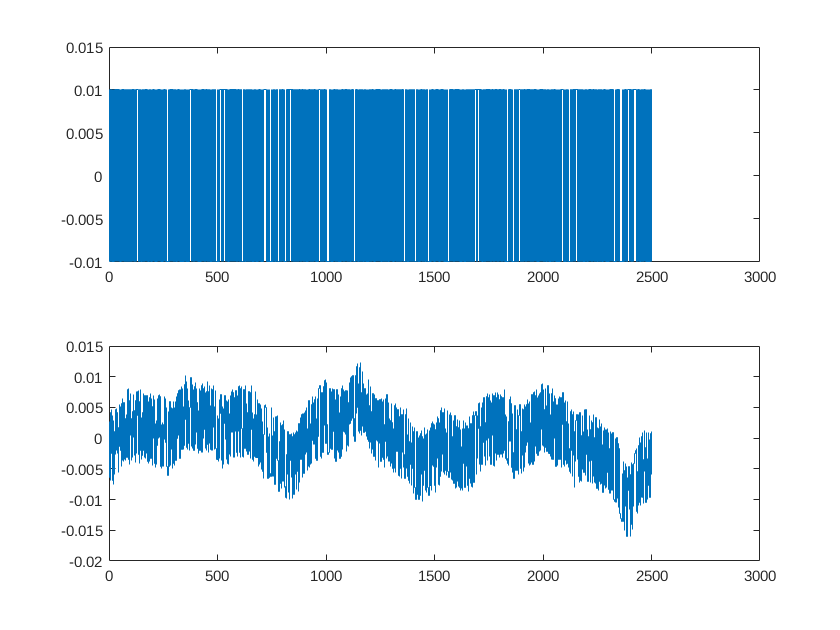

load rover-sysid.mat
skipfirst=500; % Skip first five seconds
% Remove mean
uident = detrend(out.Data(skipfirst:end,1), 0);
yident = detrend(out.Data(skipfirst:end,2), 0);
figure()
subplot(211);
stairs(uident)
subplot(212)
stairs(yident)

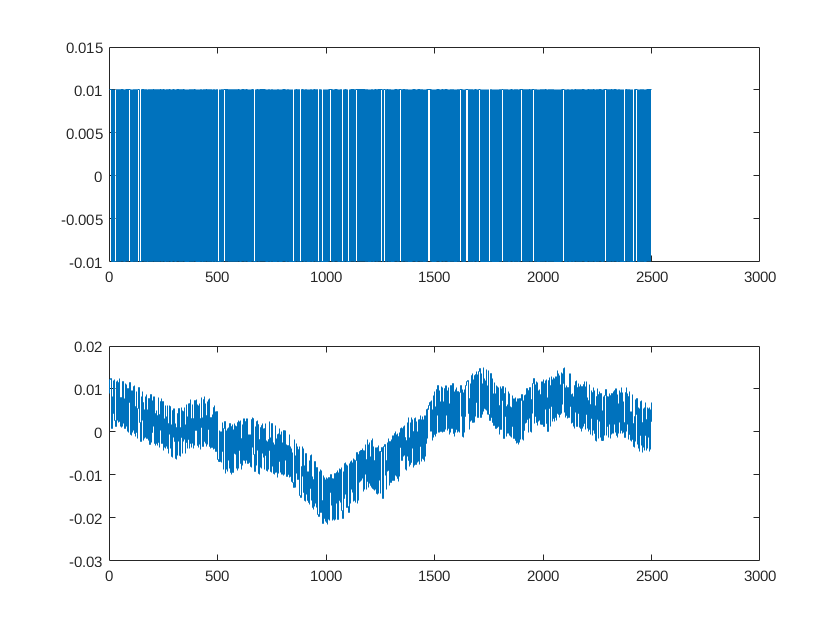


load rover-sysid-val.mat
uval = detrend(out.Data(skipfirst:end,1), 0);
yval = detrend(out.Data(skipfirst:end,2), 0);

figure()

subplot(211);
stairs(uval)
subplot(212)
stairs(yval)

## Estimate models

iddta1 = iddata(yident,uident, h);
valdta1 = iddata(yval, uval, h);

% first order model, one zero, one pole, no delay
% (b0 z + b1) / (z + a1)
arx110 = arx(iddta1, [1, 1, 0])

% Second order model, one zero, two poles, one delay
% (b0 z + b1) / (z^2 + a1z + a2)
arx221 = arx(iddta1, [2, 2, 1])

arx221 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.8159 z^-1 - 0.1198 z^-2             
                                                   
  B(z) = -0.05394 z^-1 - 0.1881 z^-2               
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 30.93% (prediction focus)
FPE: 1.212e-05, MSE: 1.206e-05                   



% Second order model, one zero, two poles, two delays
% (b0 z + b1) /(z*(z^2 + a1z + a2))
arx222 = arx(iddta1, [2, 2, 2])

arx222 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.6743 z^-1 - 0.2505 z^-2             
                                                   
  B(z) = -0.2135 z^-2 - 0.008034 z^-3              
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=2
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 30.88% (prediction focus)
FPE: 1.214e-05, MSE: 1.208e-05                   



% fourth order model, three zeros, four poles, one delay
% (b0 z^3 + b1z^2 + b2z + b3) / (z^4 + a1z^3 + a2z^2 + a3z + a4)
arx441 = arx(iddta1, [4, 4, 1])

arx441 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)             
  A(z) = 1 - 4.253 z^-1 + 5.507 z^-2 - 2.147 z^-3 - 0.04524 z^-4
                                                                
  B(z) = -1.28 z^-1 + 1.255 z^-2 + 0.008174 z^-3 - 0.2381 z^-4  
                                                                
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 31.58% (prediction focus)
FPE: 1.195e-05, MSE: 1.183e-05                   


## Compare models

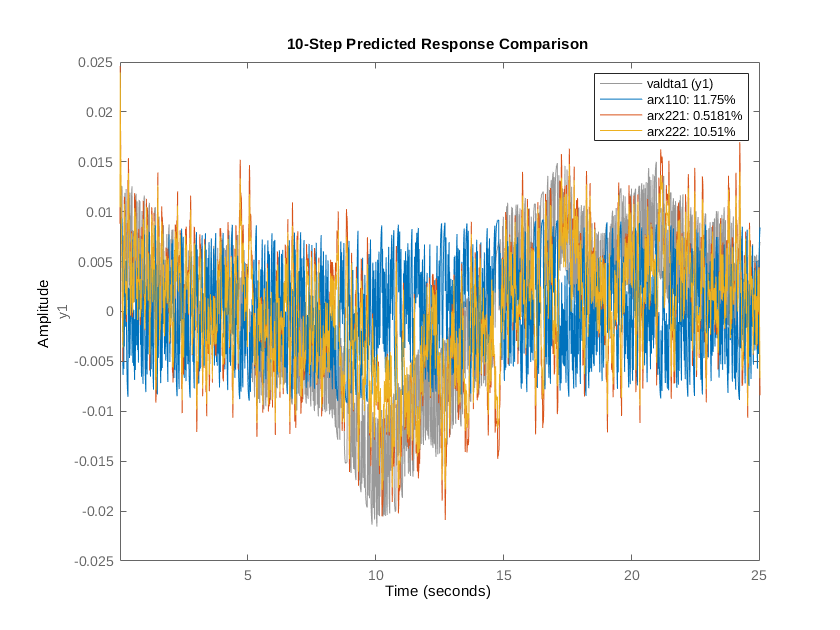

compare(valdta1, arx110,arx221, arx222,10)

aic(arx110,arx221, arx222)

Model quality according to the "nAIC" measure:
  -12.9657  -11.3208  -11.3193



## Export models for use in Simulink

[num, den] = tfdata(tf(arx221))

num = 1×1 cell array
    {[0 -0.0539 -0.1881]}


den = 1×1 cell array
    {[1 -0.8159 -0.1198]}


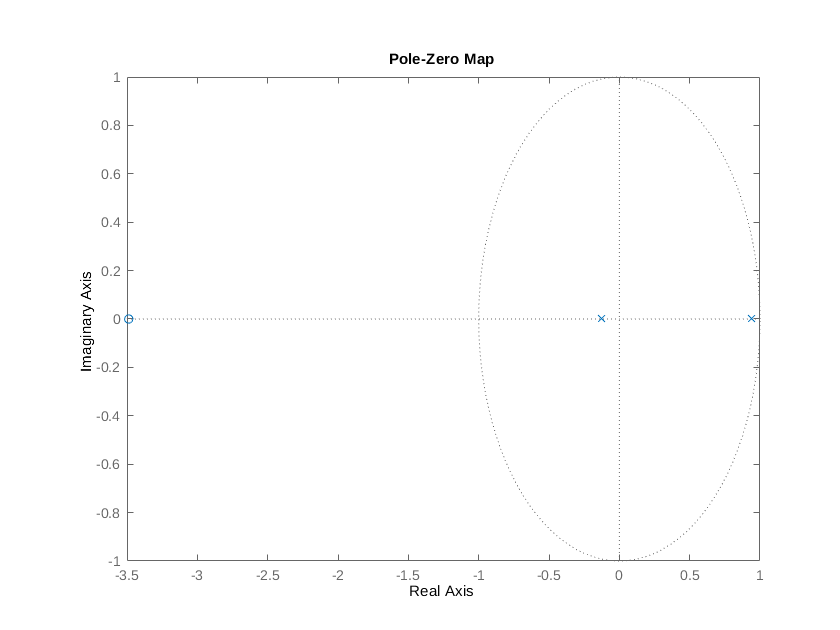

figure()
pzmap(tf(arx221))